Przykład 1. Złe przedstawienie wykresu.

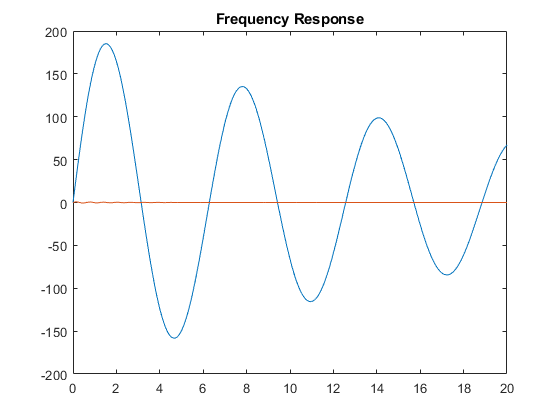

% Create some data for the two curves to be plotted
x  = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% Create a plot with 2 y axes using the yyaxis function
figure
plot(x, y1)
hold on
plot(x, y2)
hold off
% Add title and x axis label
title('Frequency Response')

Przykład 2. Złe przedstawienie danych

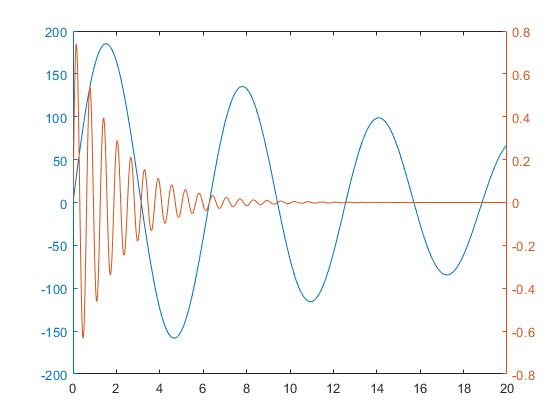

% Create some data for the two curves to be plotted
x  = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% Create a plot with 2 y axes using the yyaxis function
figure
yyaxis left
plot(x, y1)
yyaxis right
plot(x, y2)

Przykład 3. Dobre przedstawienie danych.

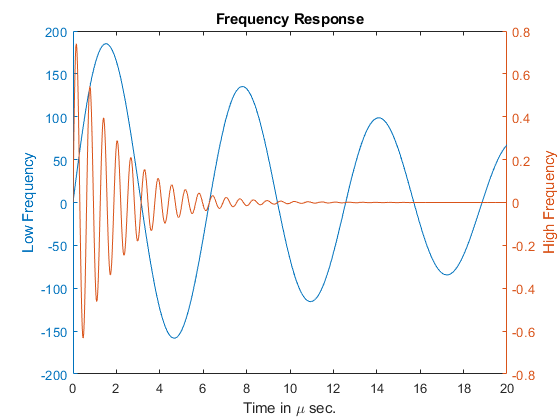

% Create some data for the two curves to be plotted
x  = 0:0.01:20;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
% Create a plot with 2 y axes using the yyaxis function
figure
yyaxis left
plot(x, y1)
ylabel('Low Frequency')
yyaxis right
plot(x, y2)
ylabel('High Frequency')
% Add title and x axis label
xlabel('Time in \mu sec.')
title('Frequency Response')

Zadanie 0a. 

Przedstaw na jednym wykresie funkcję: $x^2 -y^2 =c$ w zależności od parametru $c\in \left\lbrace -4,-2,0,2,4\right\rbrace$. Przedstaw wyniki na jednym wykresie.

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

c = [ -4 -2 0 2 4 ];
figure
hold on
title("Wykres x^2 - y^2 = c")

for i = 1:size(c, 2)
    fimplicit(@(x, y) x^2 - y^2 - c(i))
end

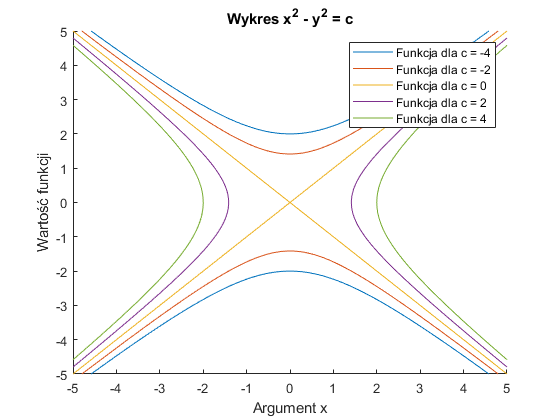

xlabel("Argument x")
ylabel("Wartość funkcji")
legend('Funkcja dla c = -4', 'Funkcja dla c = -2', "Funkcja dla c = 0", "Funkcja dla c = 2", "Funkcja dla c = 4")

Zadanie 0b.

Dane są funkcję: $f\left(x\right)=x^2$ oraz $g\left(x\right)=5+\sin \left(x\right)$

Rozwiąż graficznie równanie: $f\left(x\right)=g\left(x\right)$

Przedstaw w dwóch postaciach:

- użyj legendy do opisu wykresu,

- użyj funkcji text by narzucić tekst na wykres

Nadaj tytuł, podpisz osie (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

syms x y
f = x^2;
g = 5 + sin(x);
% na skutek błędu Matlaba, nie działa znajdywanie wszystkich rozwiązywań
x0 = [ vpasolve(f == g, x,[-3 -1]) vpasolve(f == g, x,[2 3]) ];
figure
hold on
title("Wykres funkcji f oraz g")
xlabel("Argument x")
ylabel("Wartość funkcji")
fplot(@(x) x^2, "r")

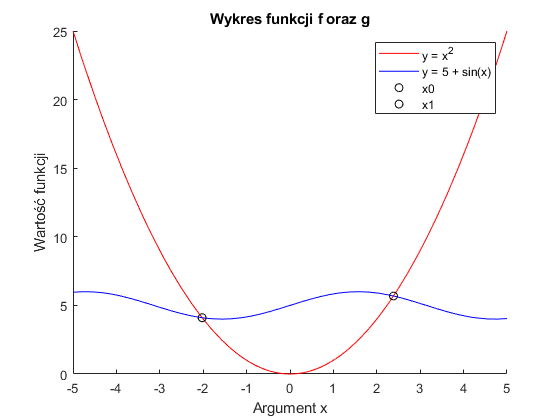

fplot(@(x) 5 + sin(x), "b")
for i=1:size(x0, 2)
    plot(x0(i), x0(i)^2, "ok")
end
legend("y = x^2", "y = 5 + sin(x)", "x0", "x1")

Wczytywanie pliku:

- load

- xlsread

- readmatrix

- readtable

- readcell

Zadanie 1. 

Wczytaj plik ***temperatury.xlsx ***

Przedstaw dane na wykresie (wykresach) oraz jednym oknie. 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

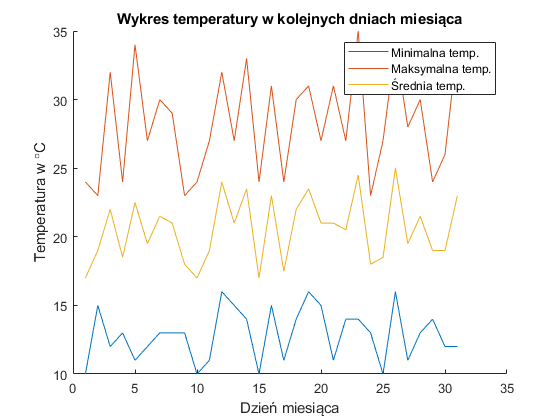

mat = xlsread("temperatury.xlsx");
figure
hold on
title("Wykres temperatury w kolejnych dniach miesiąca")
xlabel("Dzień miesiąca")
ylabel("Temperatura w \circC")
for x=1:size(mat)
    for rct=2:size(mat(x,:), 2)
        i = mat(x, rct);
    end
end
dni = mat(:, 1);
miny = mat(:, 2);
maxy = mat(:, 3);
srednie = mat(:, 4);
plot(dni, miny)
plot(dni, maxy)
plot(dni, srednie)
legend("Minimalna temp.", "Maksymalna temp.", "Średnia temp.")

Zadanie 2. 

Wczytaj plik ***pogoda.xlsx***

Przedstaw dane na wykresie (wykresach). 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

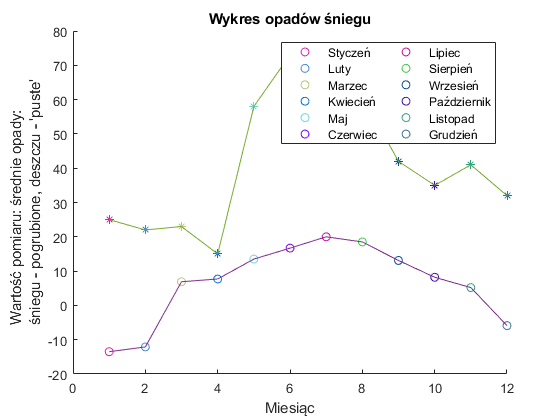

clear
mat = xlsread("pogoda.xlsx");
figure
hold on
colr = rand(size(mat, 1), 3);
title("Wykres opadów śniegu")
xlabel("Miesiąc")
ylabel("Wartość pomiaru: średnie opady:\newlineśniegu - pogrubione, deszczu - 'puste'")
paryHandle = [];
tmp = []; % do przechowywania handle do plotów, aby połączyć legendy
for x=1:size(mat)
    for rct=1:size(mat(x,:), 2)
        i = mat(x, rct);
        if rct == 1
            tmp = plot(x, i, "o", "Color", colr(x, :));
        else
            paryHandle = [paryHandle; [tmp plot(x, i, "*", "Color", colr(x, :))]];
        end
    end
end
plot(1:1:12, mat(:, 1))
plot(1:1:12, mat(:, 2))
lg = legend([paryHandle(1), paryHandle(2), paryHandle(3), paryHandle(4), paryHandle(5), paryHandle(6), paryHandle(7), paryHandle(8), paryHandle(9), paryHandle(10), paryHandle(11), paryHandle(12)], "Styczeń", "Luty", "Marzec", "Kwiecień", "Maj", "Czerwiec", "Lipiec", "Sierpień", "Wrzesień", "Październik", "Listopad", "Grudzień");
lg.NumColumns = 2;

Zadanie 3. 

Załaduj wbudowane dane ***gas.mat***

Przedstaw dane na wykresie (wykresach). 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

mat = load("gas.mat");
figure
title("Cena paliwa w okolicach Massachusetts w 1993 roku")
xlabel("Identyfikator sprzedawcy")
ylabel("Cena sprzedaży za jednostkę")
hold on
transpose(mat.price1)

ans =    119   117   115   116   112   121   115   122   116   118   109   112   119   112   117   113   114   109   109   118


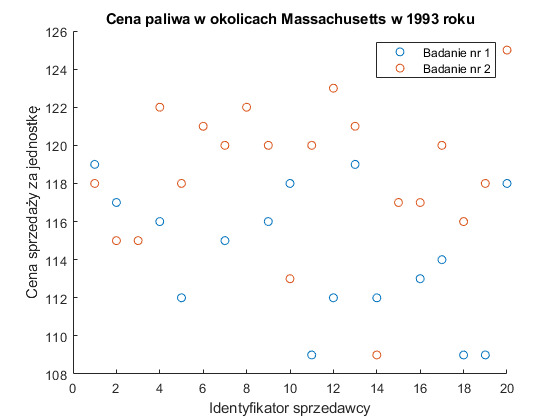

plot(1:1:size(mat.price1, 1), mat.price1, "o")
plot(1:1:size(mat.price2, 1), mat.price2, "o")
legend("Badanie nr 1", "Badanie nr 2")

Zadanie 4*. 

Załaduj wbudowane dane ***cereal.mat***

Przedstaw wybrane dane na wykresie (wykresach). Nadaj tytuł, podpisz osie, dodaj legendę.

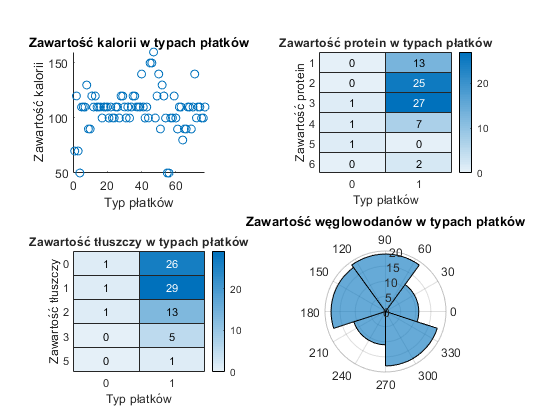

strct = load("cereal.mat");
figure
subplot(2, 2, 1)
scatter(1:1:size(strct.Type, 1), [strct.Calories])
title("Zawartość kalorii w typach płatków")
xlabel("Typ płatków")
ylabel("Zawartość kalorii")
subplot(2, 2, 2)
heatmap(table(strct.Type, strct.Protein), "Var1", "Var2");
title("Zawartość protein w typach płatków")
xlabel("Typ płatków")
ylabel("Zawartość protein")
subplot(2, 2, 3)
heatmap(table(strct.Type, strct.Fat), "Var1", "Var2");
title("Zawartość tłuszczy w typach płatków")
xlabel("Typ płatków")
ylabel("Zawartość tłuszczy")
subplot(2, 2, 4)
polarhistogram([strct.Carbo])
title("Zawartość węglowodanów w typach płatków")

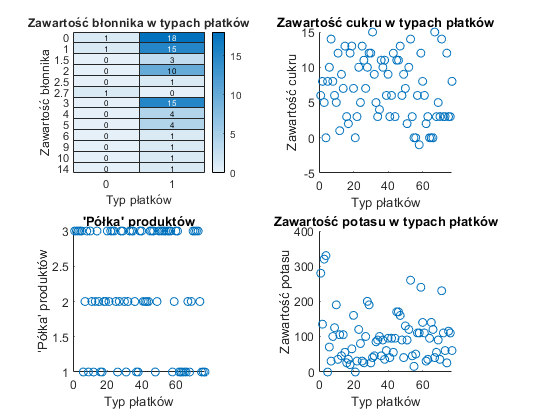

figure
subplot(2, 2, 1)
heatmap(table(strct.Type, strct.Fiber), "Var1", "Var2");
title("Zawartość błonnika w typach płatków")
xlabel("Typ płatków")
ylabel("Zawartość błonnika")
subplot(2, 2, 2)
scatter(1:1:size(strct.Type, 1), [strct.Sugars])
title("Zawartość cukru w typach płatków")
xlabel("Typ płatków")
ylabel("Zawartość cukru")
subplot(2, 2, 3)
scatter(1:1:size(strct.Type, 1), [strct.Shelf])
title("'Półka' produktów")
xlabel("Typ płatków")
ylabel("'Półka' produktów")
subplot(2, 2, 4)
scatter(1:1:size(strct.Type, 1), [strct.Potass])
title("Zawartość potasu w typach płatków")
xlabel("Typ płatków")
ylabel("Zawartość potasu")

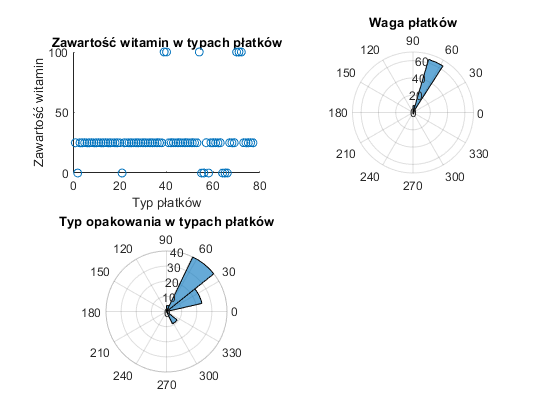

figure
subplot(2, 2, 1)
scatter(1:1:size(strct.Type, 1), [strct.Vitamins])
title("Zawartość witamin w typach płatków")
xlabel("Typ płatków")
ylabel("Zawartość witamin")
subplot(2, 2, 2)
polarhistogram([strct.Weight])
title("Waga płatków")
subplot(2, 2, 3)
polarhistogram([strct.Cups])
title("Typ opakowania w typach płatków")

Zadanie 5*. 

Załaduj wbudowane dane ***cities.mat***

Przedstaw wybrane dane na wykresie (wykresach). 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

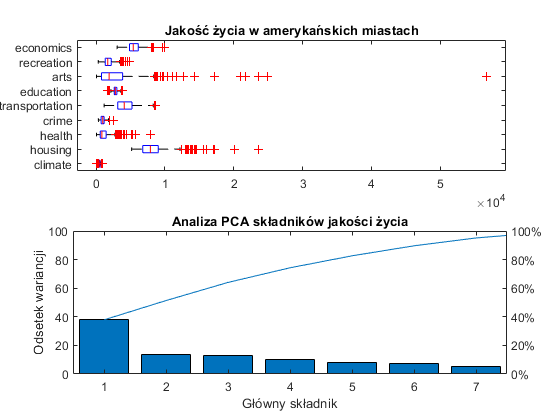

strct = load("cities.mat");
subplot(2,1,1)
boxplot(strct.ratings,'Orientation','horizontal','Labels',strct.categories)
title("Jakość życia w amerykańskich miastach")
C = corr(strct.ratings,strct.ratings);
w = 1./var(strct.ratings);
[wcoeff,score,latent,tsquared,explained] = pca(strct.ratings,'VariableWeights',w);
coefforth = inv(diag(std(strct.ratings)))*wcoeff;
subplot(2,1,2)
pareto(explained)
xlabel('Główny składnik')
ylabel('Odsetek wariancji')
title("Analiza PCA składników jakości życia")

Zadanie 6. 

Załaduj wbudowane dane*** FisherIris.mat***

Podziel dane *mean* według gatunku 

((1,50)->setosa, 

(51,100)-> virginica, 

(101,151)-> versicolor)

Policz średnią i odchylenie dla każdej kolumny, utwórz errorbar. 

Nadaj tytuł, podpisz osie, dodaj legendę (opis ma być dokładny oraz precyzyjny). Dopisz wnioski i spostrzeżenia.

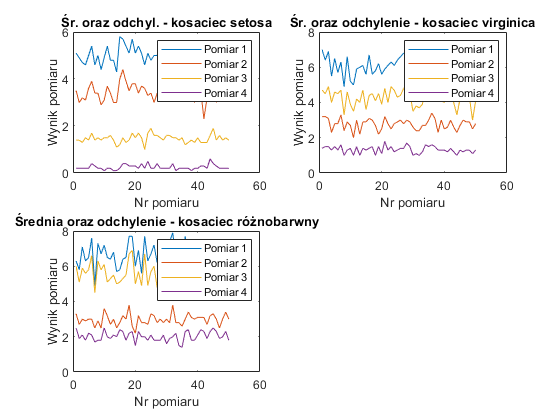

mat = load("fisheriris.mat");

setosa = mat.meas(1:50, :);
virginica = mat.meas(51:100, :);
% w treści polecenia wkradł się błąd, gdyż ostatni indeks pionowy macierzy wynosi 150
versicolor = mat.meas(101:150, :);

figure
subplot(2, 2, 1)
plot(setosa)
title("Śr. oraz odchyl. - kosaciec setosa")
xlabel("Nr pomiaru")
ylabel("Wynik pomiaru")
legend("Pomiar 1", "Pomiar 2", "Pomiar 3", "Pomiar 4")
subplot(2, 2, 2)
plot(virginica)
title("Śr. oraz odchylenie - kosaciec virginica")
xlabel("Nr pomiaru")
ylabel("Wynik pomiaru")
legend("Pomiar 1", "Pomiar 2", "Pomiar 3", "Pomiar 4")
subplot(2, 2, 3)
plot(versicolor)
title("Średnia oraz odchylenie - kosaciec różnobarwny")
xlabel("Nr pomiaru")
ylabel("Wynik pomiaru")
legend("Pomiar 1", "Pomiar 2", "Pomiar 3", "Pomiar 4")

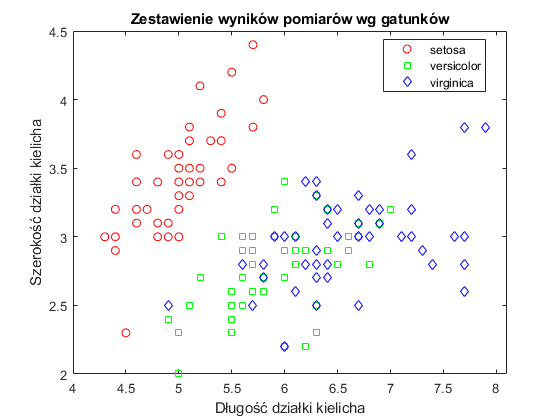


% dodatkowo - zestawienie wyników pomiarów wg gatunków
figure
gscatter(mat.meas(:,1), mat.meas(:,2), mat.species,'rgb','osd');
title("Zestawienie wyników pomiarów wg gatunków")
xlabel('Długość działki kielicha');
ylabel('Szerokość działki kielicha');

N = size(mat.meas,1);

Zadanie 7*. 

Załaduj wbudowane dane ***spine X***

Przedstaw dane X na wykresach różnych wykresach (plot, hist,mesh). Spróbuj na podstawie wykresów zgadnąć co to za dane.

Na końcu użyj funkcji imagesc(X).

Dopisz wnioski i spostrzeżenia.

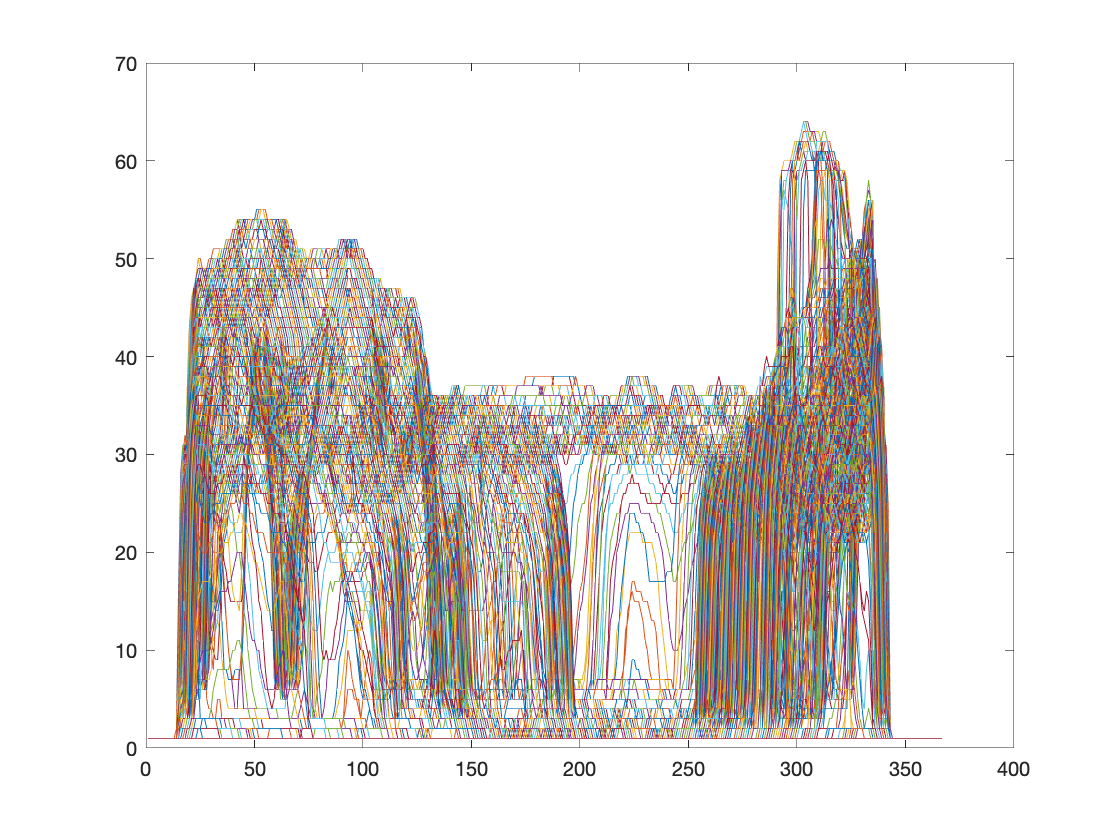

mat = load("spine.mat", "X");
plot(mat.X);

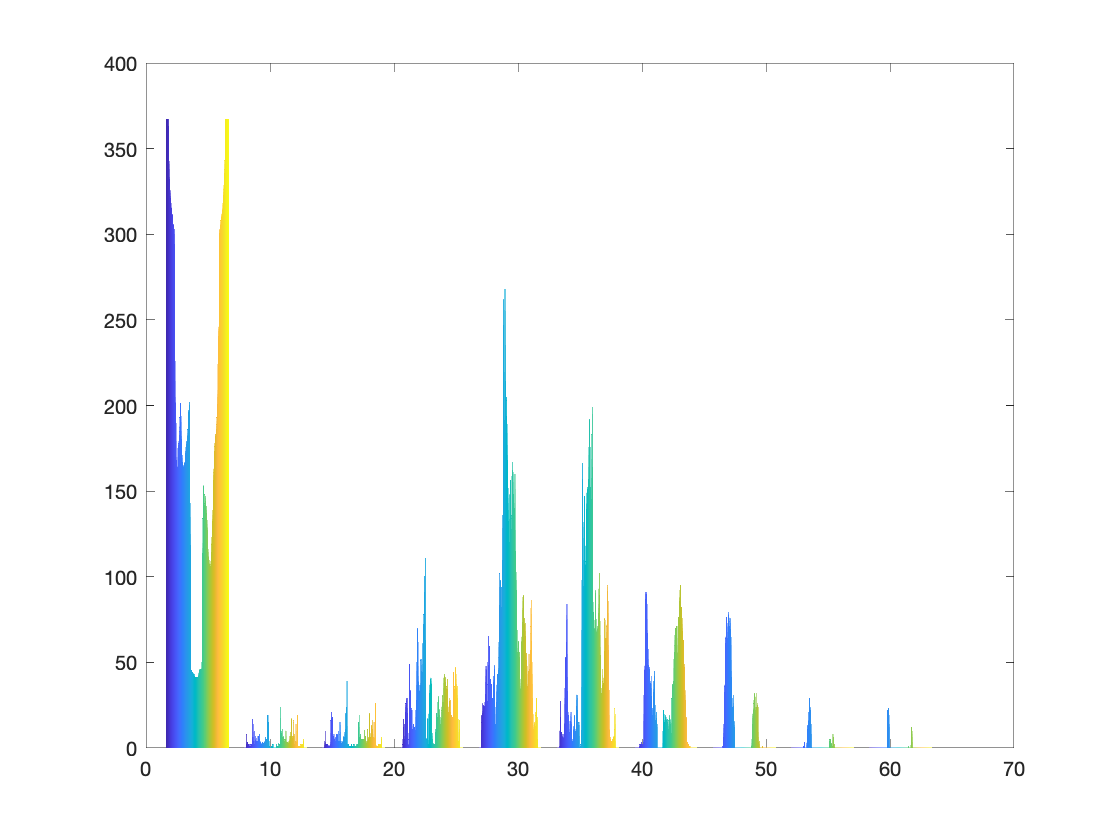

hist(mat.X);

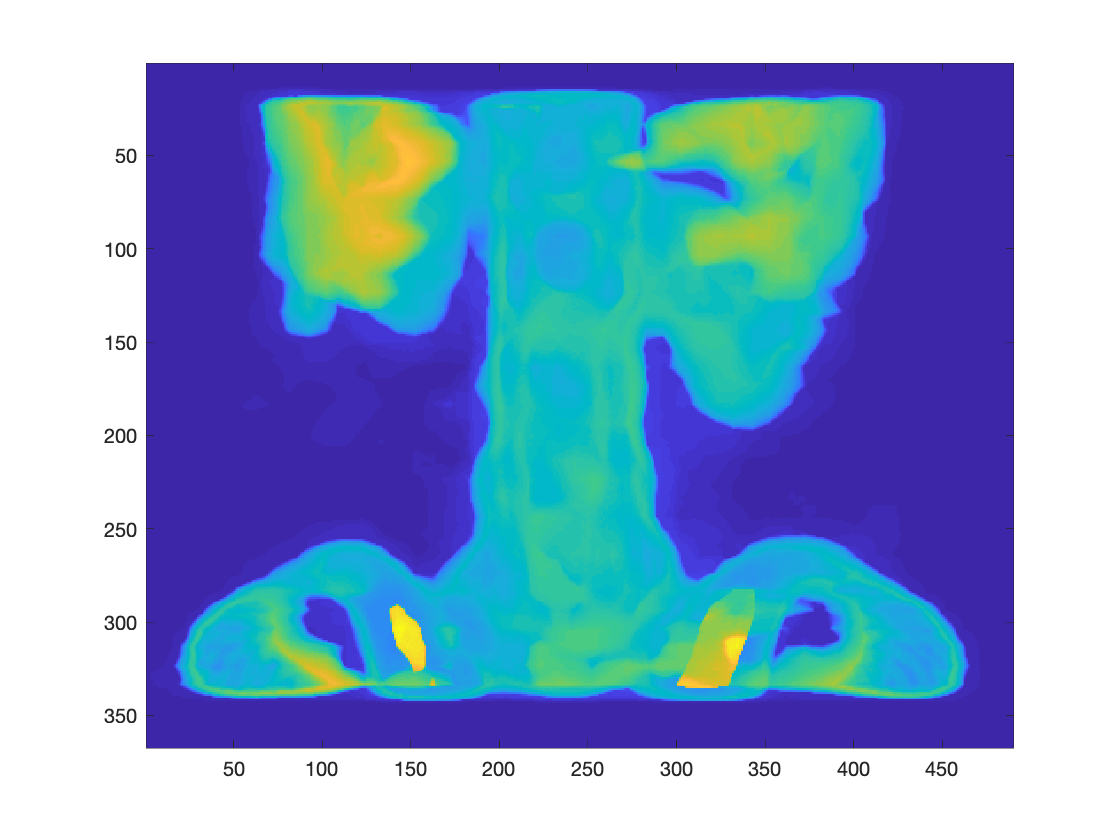

% poniższy mesh nie działa, gdyż występuje błąd
% dotyczący próby alokacji zbyt dużej ilości danych
% (~43 mln GB), co znaczy, że zestaw danych będzie duży
% lub będzie kodował bitmapę lub inną strukturę multimedialną
%[X,Y,Z] = meshgrid(mat.X);
%mesh(X,Y,Z);ś
imagesc(mat.X);

% w tym kroku widać wyraźnie, że zestaw danych koduje plik multimedialny -
% bitmapę - prześwietlenie odcinka kręgosłupa

% Wnioski
% Narzędzie Matlab pozwala na precyzyjną wizualizację danych, które chcemy analizować.
% Uważać należy na dobór zakresu osi, by uchwycić interesujące informacje.
% Do poprawnego przedstawienia danych konieczne jest dobranie odpowiedniego
% typu wykresu, przedziałów osi, a także skali i opisanie elementów wykresu
% W przypadku szukania punktów przecięcia (zadanie 0b) wykres pomocniczy przydatny jest w określeniu
% przedziałów, w których chcemy zadać Matlabowi szukanie interesujących nas punktów
% W zadanie 7-mym zbędne natomiast było wizualizowanie danych używając
% jakichkolwiek funkcji grafujących, gdyż kodowały one plik multimedialny